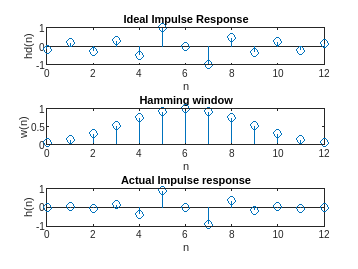

clc;clear;close all;
N=13;
alpha=(N-1)/2;
n=0:N-1;
hd=(cos(pi*(n-alpha)))./(n-alpha);
hd(alpha+1)=0;
w_ham=(hamming(N))';
h=hd.*w_ham;
subplot(311),stem(n,hd),title('Ideal Impulse Response');
xlabel('n'),ylabel('hd(n)');
subplot(312),stem(n,w_ham),title('Hamming window');
xlabel('n'),ylabel('w(n)');
subplot(313),stem(n,h),title('Actual Impulse response');
xlabel('n'),ylabel('h(n)');

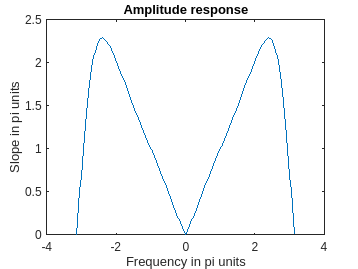


freq_rad=-pi:pi/101:pi;
H=freqz(h,1,freq_rad);
figure;
plot(freq_rad,abs(H));
xlabel('Frequency in pi units'),ylabel('Slope in pi units'),title('Amplitude response');